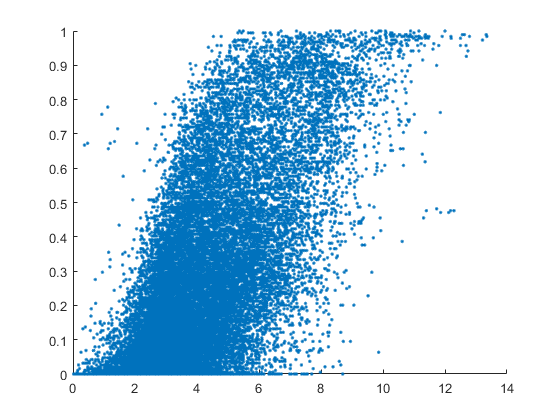


close all;
clc; 
clear;
turbina= load ('../DataSet/clean_dataset.mat');
train_data = readtable('../DataSet/train.csv');
test_data = readtable('../DataSet/test.csv');

%%

% figure;
% scatter(train_data.ws,train_data.wp1, '.', 'MarkerEdgeColor', '#D95319');
% hold on;
% scatter(turbina.turbine.ws, turbina.turbine.wp1, '.', 'MarkerEdgeColor', '#0072BD');
% grid on;
% title('Clean data from the turbine');
% xlabel('Wind Speed [m/s]');
% ylabel('Generated Power [kW]');
% legend("Detected Outliers", "Clean Data");
% 
% 
% %
% figure;
% scatter(train_data.ws, train_data.wp1, '.');
% grid on;
% title('Identification Set');
% xlabel('Windspeed [m/s]');
% ylabel('Generated Power [kW]');
% 
% figure;
% scatter(test_data.ws, test_data.wp1, '.', 'r');
% grid on;
% title('Test Set');
% xlabel('Wind Speed [m/s]');
% ylabel('Generated Power [kW]');
% 
% % figure;
% % scatter(test_data.ws, test_data.wp1, '.');
% % grid on;
% % title('Validation Set');
% % xlabel('Wind Speed [m/s]');
% % ylabel('Generated Power [kW]');
% 
% 
% %% Modello di benchmark (cut-in e cut-out) ovvero  fa riferimento ad una metodologia studiata per valutare le performance
% %Il modello benchmark è costuito da una semplice funzione cubica nell'intervallo incluso tra le velocità di cut-in e di cut-out.
% %dove  rho è la densità dell'aria e A è l'area della spazzata, ovvero la superficie coperta dalla pala di raggio r .
% 
% %P(v)= 1/2*rho*A*v^3
% cutin_windspeed = 1;
% cutout_windspeed = 13;
% 
% datainrange = train_data(train_data.ws > cutin_windspeed & train_data.ws <= cutout_windspeed, :);
% [theta, sigma] = lscov(datainrange.ws.^3, datainrange.wp1);
% Y_Hat = datainrange.ws.^3 * theta;
% 
% 
% %Nella sezione di saturazione per completare il modello su tutto l'intervallo di velocità del vento, uso il valore medio delle saturazioni vere e lo applico 
% %da quando la curva cubica supera il livello di saturazione
% 
 saturationValue = mean(train_data(train_data.ws > 13 , :).wp1);
% 
% 
% density = 0.01;
% saturationWindspeed = density * floor(((saturationValue / theta) ^ (1/3))*(1/density));
% windspeedGrid = [0 : density : 25]';
% 
% 
% 
% figure;
% scatter(train_data.ws, train_data.wp1, '.', 'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
% hold on;
% grid on;
% plot(windspeedGrid, benchmark_model(windspeedGrid, theta, saturationWindspeed, saturationValue), "LineWidth", 2.5);
% title('Benchmark Model: $P(v) = \theta v^3$', 'Interpreter', 'latex');
% xlabel('Wind Speed [m/s]');
% ylabel('Power [kW]');
% legend("Training Data", "Benchmark Model");
% 
% %predizione si dati di test 
% 
% Y_Hat_test = benchmark_model(test_data.ws, theta, saturationWindspeed, saturationValue);
% 
% figure;
% scatter(test_data.ws, test_data.wp1, '.');
% hold on;
% grid on;
% scatter(test_data.ws, Y_Hat_test, '.');
% title('Validation for Benchmark Model: $P(v) = \frac{1}{2}\rho Av^3$', 'Interpreter', 'latex');
% xlabel('Wind Speed [m/s]');
% ylabel('Power [kW]');
% legend("Validation Data", "Estimates");
% 
% 
% %Goodness of git (GOF)
% 
% thetaGOF = lscov([ ones(length(Y_Hat_test), 1), Y_Hat_test], test_data.wp1);
% 
% figure;
% scatter(test_data.wp1, Y_Hat_test, '.', 'MarkerFaceAlpha',.55,'MarkerEdgeAlpha',.55);
% grid on;
% hold on;
% plot([0, 1], [0,1], 'LineWidth', 2);
% plot([0, 1], thetaGOF(1) + thetaGOF(2)*[0,1], 'LineWidth', 2);
% axis([0, 1, 0, 1]);
% title('Goodness of fit for Benchmark Model: $P(v) = \theta v^3$', 'Interpreter', 'latex');
% xlabel('Actual Power [Kw]');
% ylabel('Estimated Power [kW]');
% legend("Data vs. Estimates", "$45^{\circ}$ line", "Linear Regression", "Interpreter", 'latex');
% 
% 
% benchmarkModel.parameters = theta;
% benchmarkModel.standardDeviation = sigma;
% benchmarkModel.confidenceIntervals = [theta - 1.96 * sigma, theta + 1.96*sigma];
% 
% benchmarkModel.SSR = sum((datainrange.wp1 - Y_Hat).^2);
% benchmarkModel.MSE = (1/length(Y_Hat)) * benchmarkModel.SSR;
% 
% benchmarkModel.FPE = ((length(Y_Hat) + length(theta))/(length(Y_Hat) - length(theta))) * benchmarkModel.SSR ;
% benchmarkModel.AIC = (2*length(theta) / length(Y_Hat)) * log(benchmarkModel.SSR);
% benchmarkModel.MDL = (log(length(Y_Hat))*length(theta) / length(Y_Hat)) * log(benchmarkModel.SSR);
% 
% benchmarkModel.ValidationSSR = sum((test_data.wp1 - Y_Hat_test).^2);
% benchmarkModel.ValidationMSE = benchmarkModel.ValidationSSR / length(Y_Hat_test);
% 
% benchmarkModel.MAE = (sum(abs(test_data.wp1 - Y_Hat_test))) / (length(Y_Hat_test));
% benchmarkModel.WMAPE = sum(abs(test_data.wp1 - Y_Hat_test)) / sum(abs(test_data.wp1));
% benchmarkModel.NRMSE = sqrt(benchmarkModel.ValidationMSE) / (max(test_data.wp1) - min(test_data.wp1));

%Modelli cubici

cutin_windspeed = 1;
cutout_windspeed = 13;

datainrange = train_data(train_data.ws < cutout_windspeed & train_data.ws > cutin_windspeed, :);

PHI = [datainrange.ws, datainrange.ws.^2, datainrange.ws.^3];
[theta, sigma] = lscov(PHI, datainrange.wp1);
Y_Hat = PHI*theta;

density = 0.01;
windspeedGrid = [cutin_windspeed : density : cutout_windspeed]';
PHIGrid = [windspeedGrid, windspeedGrid.^2, windspeedGrid.^3];
Y_Hat_grid = PHIGrid * theta;

cutinTD = max(windspeedGrid(Y_Hat_grid <= 0));
cutoutTD =  min(windspeedGrid(Y_Hat_grid >= saturationValue));

windspeedGrid = [0 : density : 25]';

figure;
scatter(train_data.ws, train_data.wp1, '.' , 'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
hold on;

plot(windspeedGrid, secondo(windspeedGrid, theta, cutoutTD, saturationValue, cutinTD), "LineWidth", 2.5);

Error: File: secondo.mlx Line: 10 Column: 13
Invalid use of operator.

grid on;
title('Model: $P(v) = \theta_1 v + \theta_2 v^2 + \theta_3 v^3$', 'Interpreter', 'latex');
xlabel('Wind Speed [m/s]');
ylabel('Power [kW]');
legend("Training Data", "Cubic Model");



Y_Hat_validation = thirdDegree_model(validationSet.windspeed, theta, cutoutTD, saturationValue, cutinTD);

figure;
scatter(validationSet.windspeed, validationSet.power, '.');
hold on;
scatter(validationSet.windspeed, Y_Hat_validation, '.');
grid on;
title('Validation for Model: $P(v) = \theta_1 v + \theta_2 v^2 + \theta_3 v^3$', 'Interpreter', 'latex');
xlabel('Wind Speed [m/s]', "Interpreter", 'latex');
ylabel('Power [kW]', "Interpreter", 'latex');
legend("Validation Data", "Estmates", "Interpreter", 'latex');


Goodness Of fit
thetaGOF = lscov([ ones(length(Y_Hat_validation), 1), Y_Hat_validation], test_data.wp1);

figure;
scatter(test_data.wp1, Y_Hat_validation, '.', 'MarkerFaceAlpha',.55,'MarkerEdgeAlpha',.55);
grid on;
hold on;
plot([0, 3800], [0,3800], 'LineWidth', 2);
plot([0, 3800], thetaGOF(1) + thetaGOF(2)*[0,3800], 'LineWidth', 2);
axis([0, 3800, 0, 3800]);
title('Goodness of fit for Model: $P(v) = \theta_1 v + \theta_2 v^2 + \theta_3 v^3$', 'Interpreter', 'latex');
xlabel('Actual Power [kW]', "Interpreter", 'latex');
ylabel('Estimated Power [kW]', "Interpreter", 'latex');
legend("Data vs. Estimates", "$45^{\circ}$ line", "Regression Line", "Interpreter", 'latex');

%Test

cubicModel_third.parameters = theta;
cubicModel_third.standardDeviation = sigma;
cubicModel_third.confidenceIntervals = [theta - 1.96 * sigma, theta + 1.96*sigma];

cubicModel_third.SSR = sum((datainrange.wp1 - Y_Hat).^2);
cubicModel_third.MSE = cubicModel_third.SSR / length(Y_Hat);

cubicModel_third.FPE = ((length(Y_Hat) + length(theta))/(length(Y_Hat) - length(theta))) * cubicModel_third.SSR;
cubicModel_third.AIC = ((2*length(theta))/(length(Y_Hat)))*log(cubicModel_third.SSR);
cubicModel_third.MDL = ((log(length(Y_Hat))*length(theta)) / (length(Y_Hat))) * log(cubicModel_third.SSR);

cubicModel_third.ValidationSSR = sum((validationSet.power - Y_Hat_validation).^2);
cubicModel_third.ValidationMSE = cubicModel_third.ValidationSSR / length(Y_Hat_validation);

cubicModel_third.MAE = (sum(abs(validationSet.power - Y_Hat_validation))) / (length(Y_Hat_validation));
cubicModel_third.WMAPE = sum(abs(validationSet.power - Y_Hat_validation)) / sum(abs(validationSet.power));
cubicModel_third.NRMSE = sqrt(cubicModel_third.ValidationMSE) / (max(validationSet.power) - min(validationSet.power));



